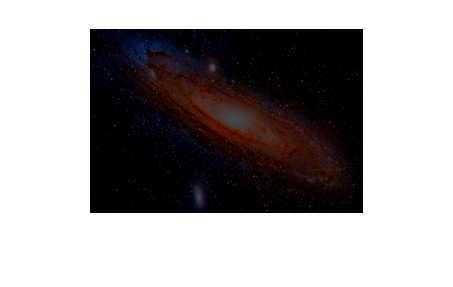

% HYPERPARAMETERS
IMG_IDX = 2;
TARGET_BRIGHTNESS = 20;
JND_FACTOR = 1;

% Reference images
ref_imgs = ["beach.jpg"; "galaxy.jpeg"; "orig.jpg"; "peacock.jpeg"; "tiger.jpg"; "toronto.jpg"; "xmas.jpg"];

% Load the image
img = imread(ref_imgs(IMG_IDX));

% Reduce the brightness
orig_brightness = compute_brightness(img);
reduction = TARGET_BRIGHTNESS/orig_brightness;
img = reduce_brightness(img, reduction,'multiply');
orig_brightness = compute_brightness(img);

% Resize image 
img = imresize(img, [360 480]); 

% Display the image
imshow(img);


% Display the average pixel intensity
disp(['Average pixel intensity: ' num2str(compute_brightness(img))]);

Average pixel intensity: 24.0316


type = 'Yang'; % idk what this parameter is lol

% Convert RGB to YCbCr
img_YCbCr = rgb2ycbcr(img);
Y = img_YCbCr(:,:,1);

% Compute the JND thresolds at a pixel level
jnd_Y = JND_pixel(Y, type);

f = 1

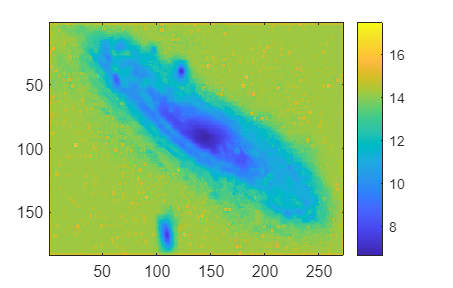


% Visualize the JND thresholds
imagesc(jnd_Y)
colorbar


% Compute the mean JND threshold
jnd_Y = JND_FACTOR.*jnd_Y;
jnd_mean = mean2(jnd_Y)

jnd_mean = 13.2545

jnd_mod = jnd_mean - jnd_Y;

% Update image based on the JND thresholds from the Y channel to generate a new image
new_img = img_YCbCr;
new_img(:,:,1) = uint8(double(Y) + round(jnd_mod));
new_img = ycbcr2rgb(new_img); % convert back to RGB
new_img(new_img < 0) = 0;
new_img(new_img > 255) = 255;

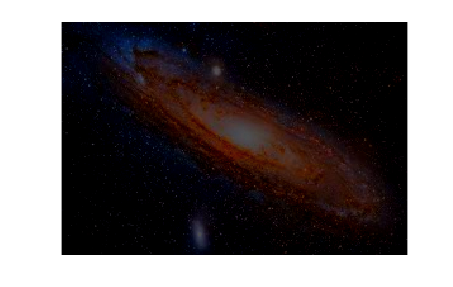

% Display the new image
imshow(new_img)


% Compute the average pixel intensity
new_brightness = compute_brightness(new_img);
intensity_dif = new_brightness - orig_brightness;

% Adjustment (if needed)
while intensity_dif > 0
    new_img = reduce_brightness(new_img, intensity_dif,'subtract');
    new_brightness = compute_brightness(new_img);
    intensity_dif = ceil(new_brightness - orig_brightness);
end

% Display the average pixel intensity
disp(['Average pixel intensity: ' num2str(new_brightness)]);

Average pixel intensity: 23.7971


% Save the images to an output directory
imwrite(img, ['output/input_image_' num2str(orig_brightness) '.jpg'], 'jpg');
imwrite(new_img, ['output/output_image_jnd_' num2str(new_brightness) '.jpg'], 'jpg');
% imwrite(new_img_uniform, ['output/output_image_uniform_' num2str(avg_intensity_uniform) '.jpg'], 'jpg');